**Real-time Digital Signal Processing Laboratory**

**Lab 3**

**Soroush Mesforush Mashhad - 810198472**

clc
clear all

Part 1

Here we shall create the given IIR elliptic filter then we shall go on to plot its frequency response.

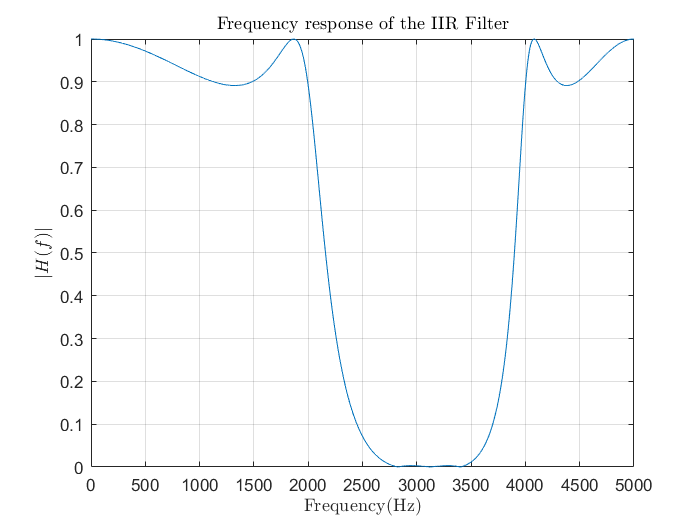

fs = 10000;
[H,fNor] = freqz(DSPLab3IIRFilter);
f = fNor*fs/(2*pi);
plot(f,abs(H));
grid on
title('Frequency response of the IIR Filter','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$|H(f)|$','Interpreter','latex');

Now we implement the filter in C and create the white noise and plot it and the output of the filters accordingly

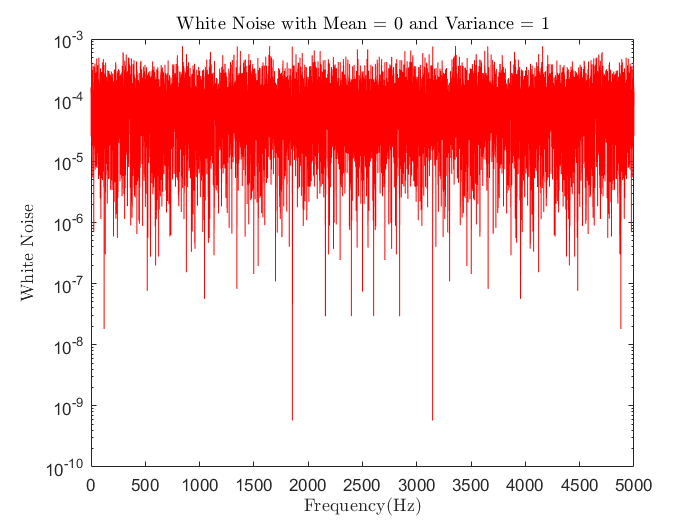

load('WhiteMean0Var1.txt')
f = linspace(0, fs/2, length(WhiteMean0Var1));
semilogy(f, (abs(fftshift(fft(WhiteMean0Var1)))/length(WhiteMean0Var1)).^2,'r')
title('White Noise with Mean = 0 and Variance = 1','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('White Noise','Interpreter','latex');

disp('The Mean is : ')

The Mean is : 


disp(mean(WhiteMean0Var1))

   2.7202e-04



disp('The Variance is : ')

The Variance is : 


disp(var(WhiteMean0Var1))

    1.0011



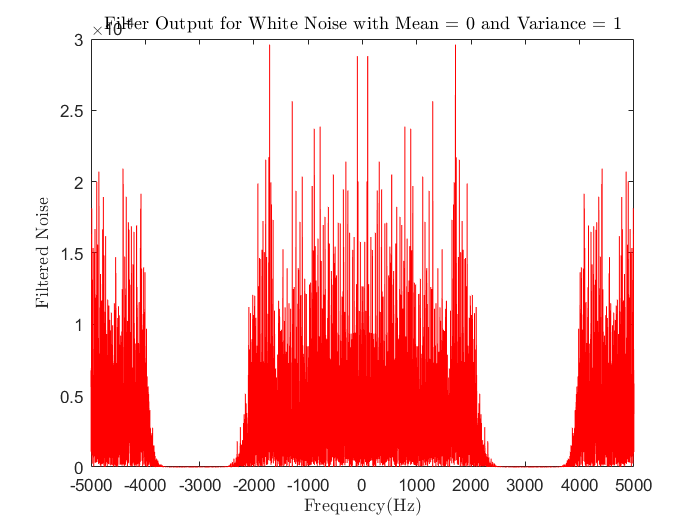

load('FilOutMean0Var1.txt')
f = linspace(-fs/2, fs/2, length(FilOutMean0Var1));
plot(f, (abs(fftshift(fft(FilOutMean0Var1)))/length(FilOutMean0Var1)).^2,'r')
title('Filter Output for White Noise with Mean = 0 and Variance = 1','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Filtered Noise','Interpreter','latex');

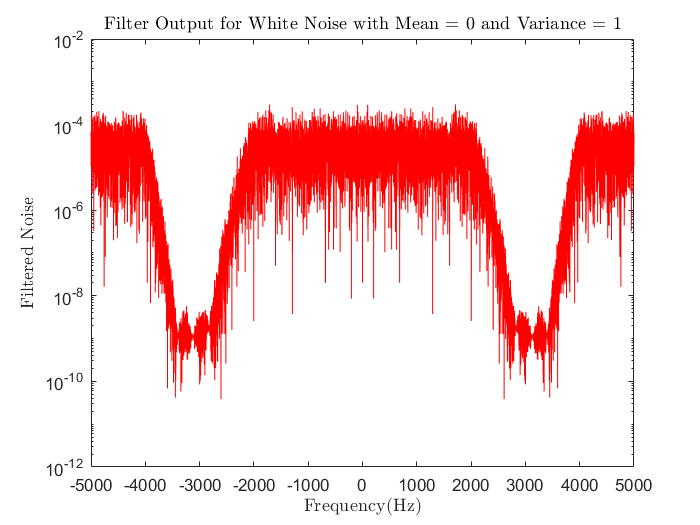

load('FilOutMean0Var1.txt')
f = linspace(-fs/2, fs/2, length(FilOutMean0Var1));
semilogy(f, (abs(fftshift(fft(FilOutMean0Var1)))/length(FilOutMean0Var1)).^2,'r')
title('Filter Output for White Noise with Mean = 0 and Variance = 1','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Filtered Noise','Interpreter','latex');

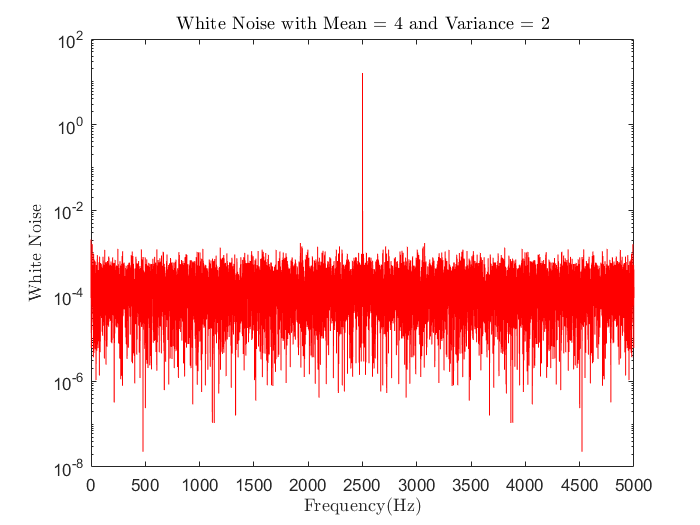

load('WhiteMean4Var2.txt')
f = linspace(0, fs/2, length(WhiteMean4Var2));
semilogy(f, (abs(fftshift(fft(WhiteMean4Var2)))/length(WhiteMean4Var2)).^2,'r')
title('White Noise with Mean = 4 and Variance = 2','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('White Noise','Interpreter','latex');

disp('The Mean is : ')

The Mean is : 


disp(mean(WhiteMean4Var2))

    4.0006



disp('The Variance is : ')

The Variance is : 


disp(var(WhiteMean4Var2))

    2.0289



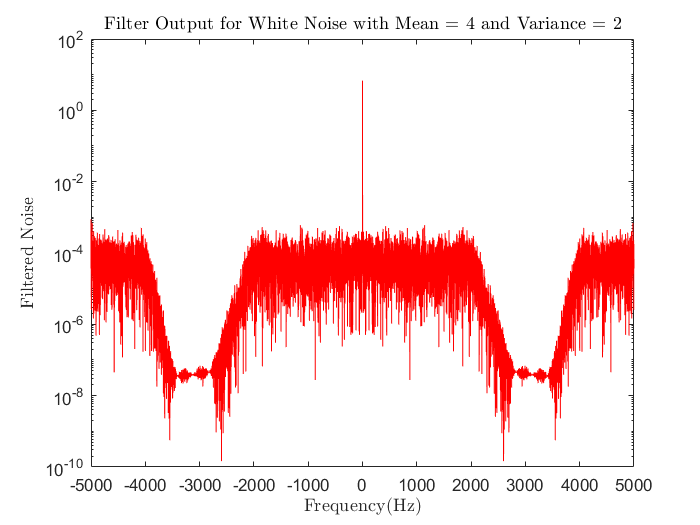

load('FilOutMean4Var2.txt')
f = linspace(-fs/2, fs/2, length(FilOutMean4Var2));
semilogy(f, (abs(fftshift(fft(FilOutMean4Var2)))/length(FilOutMean4Var2)).^2,'r')
title('Filter Output for White Noise with Mean = 4 and Variance = 2','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Filtered Noise','Interpreter','latex');

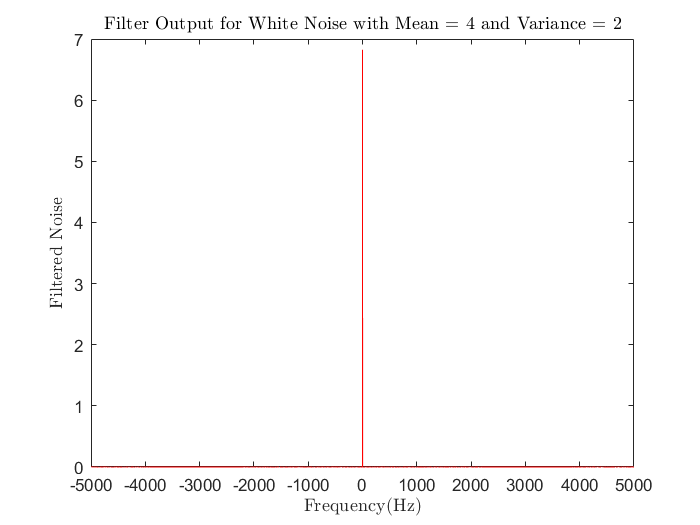

load('FilOutMean4Var2.txt')
f = linspace(-fs/2, fs/2, length(FilOutMean4Var2));
plot(f, (abs(fftshift(fft(FilOutMean4Var2)))/length(FilOutMean4Var2)).^2,'r')
title('Filter Output for White Noise with Mean = 4 and Variance = 2','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Filtered Noise','Interpreter','latex');

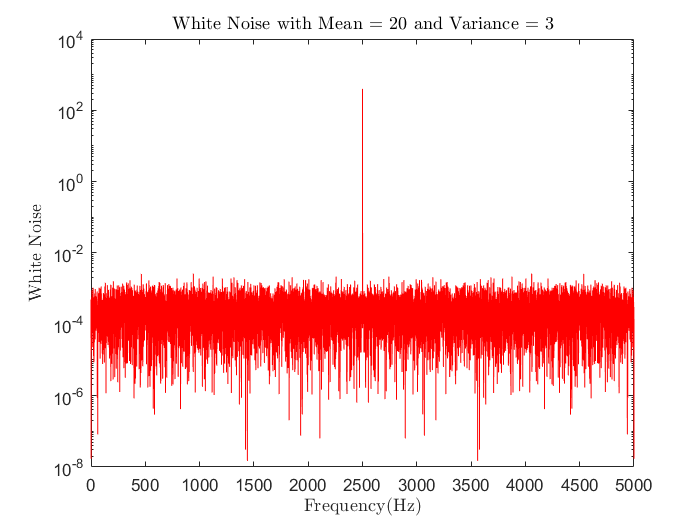

load('WhiteMean20Var3.txt')
f = linspace(0, fs/2, length(WhiteMean20Var3));
semilogy(f, (abs(fftshift(fft(WhiteMean20Var3)))/length(WhiteMean20Var3)).^2,'r')
title('White Noise with Mean = 20 and Variance = 3','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('White Noise','Interpreter','latex');

disp('The Mean is : ')

The Mean is : 


disp(mean(WhiteMean20Var3))

   20.0000



disp('The Variance is : ')

The Variance is : 


disp(var(WhiteMean20Var3))

    3.0111



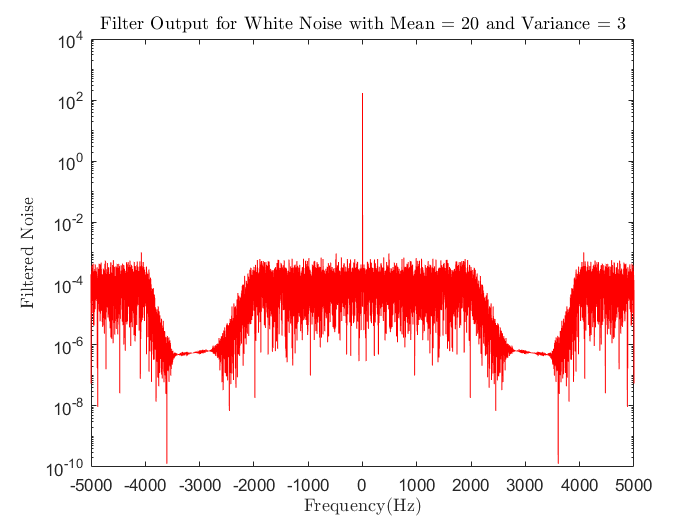

load('FilOutMean20Var3.txt')
f = linspace(-fs/2, fs/2, length(FilOutMean20Var3));
semilogy(f, (abs(fftshift(fft(FilOutMean20Var3)))/length(FilOutMean20Var3)).^2,'r')
title('Filter Output for White Noise with Mean = 20 and Variance = 3','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Filtered Noise','Interpreter','latex');

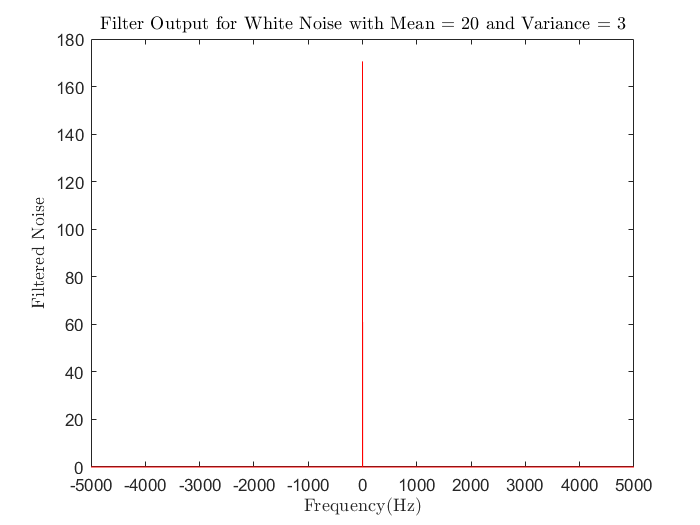

load('FilOutMean20Var3.txt')
f = linspace(-fs/2, fs/2, length(FilOutMean20Var3));
plot(f, (abs(fftshift(fft(FilOutMean20Var3)))/length(FilOutMean20Var3)).^2,'r')
title('Filter Output for White Noise with Mean = 20 and Variance = 3','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Filtered Noise','Interpreter','latex');

Part 2

Here we shall implement the echo system

Fs = 16000;
nBits = 8;
nChannels = 1;
MyVoice = audiorecorder(Fs,nBits,nChannels)

MyVoice =   audiorecorder with properties:

       SampleRate: 16000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


recDuration = 10;
disp("Begin speaking.")

Begin speaking.


recordblocking(MyVoice,recDuration);
disp("End of recording.")

End of recording.


y = getaudiodata(MyVoice);
audiowrite('MyVoice.wav',y,Fs);

gain = [0.2, 0.5, 0.7, 0.8, 1,1.2];
N = 1e3;
[MyAudio, FS] = audioread("MyVoice.wav");


[num1,denum1] = FilterCreator(gain(1),N);
[num2,denum2] = FilterCreator(gain(2),N);
[num3,denum3] = FilterCreator(gain(3),N);
[num4,denum4] = FilterCreator(gain(4),N);
[num5,denum5] = FilterCreator(gain(5),N);
[num6,denum6] = FilterCreator(gain(6),N);

echo1 = filter(num1, denum1, MyAudio);
echo2 = filter(num2, denum2, MyAudio);
echo3 = filter(num3, denum3, MyAudio);
echo4 = filter(num4, denum4, MyAudio);
echo5 = filter(num5, denum5, MyAudio);
echo6 = filter(num6, denum6, MyAudio);

audiowrite('EchoG0.2.wav',echo1,FS);
audiowrite('EchoG0.5.wav',echo2,FS);
audiowrite('EchoG0.7.wav',echo3,FS);
audiowrite('EchoG0.8.wav',echo4,FS);
audiowrite('EchoG1.wav',echo5,FS);
audiowrite('EchoG1.2.wav',echo6,FS);